# Planteamiento de la cinemática directa de la postura para un robot 4R

## Resumen

El modelo cinemático directo es fundamental en la robótica, ya que permite calcular la posición y orientación del extremo del robot (efector final) en función de los ángulos de las articulaciones. Este análisis es clave para aplicaciones donde se requiere precisión en el posicionamiento del robot. A través de la simulación, se visualiza la configuración del robot, proporcionando una base sólida para su posterior análisis.

## Definición de las funcines 

Matriz de transformaciones homógeneas

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Plateamiento del modelo de la cinemática directa del robot

El modelo del robot se plantea estableciendo las relaciones de posición y orientación de cada eslabón mediante sistemas de referencia relativos asociados a ellos. En la Figura 1 se muestra la simulación de un robot 4R, en la cual los eslabones que conforman el brazo y el antebrazo están desfasados para garantizar un movimiento libre, evitando interferencias entre sí. No obstante, en la práctica, los orígenes de los sistemas de referencia estarían perfectamente alineados, como se observa en la Figura 2.

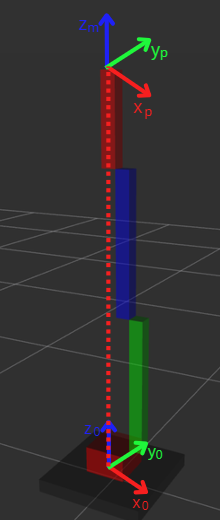

Figura 1: *Simulación de un robot 4R*

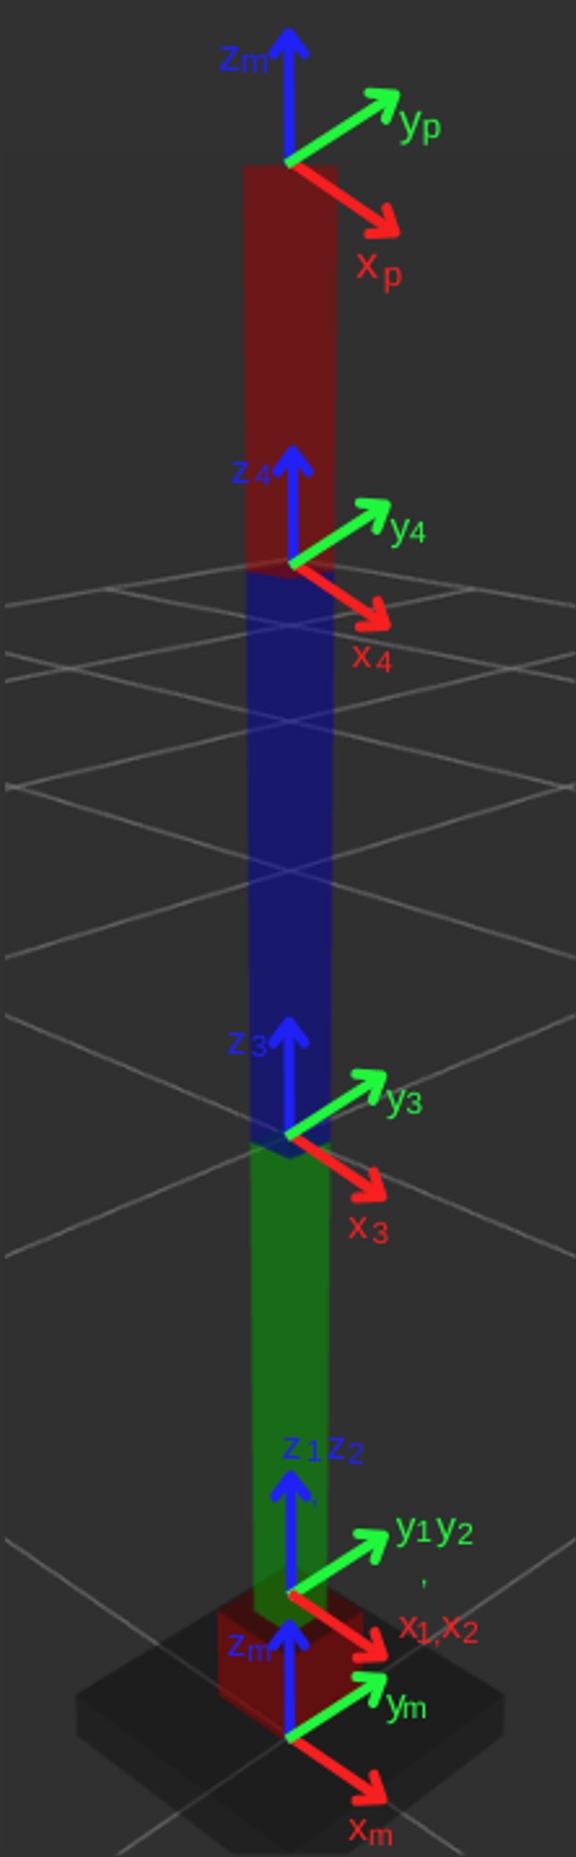

Figura 2: *Configuración alineada de sistemas de referencia en un robot 4R*.

En sistma de referencia {m} está asociacdo al sistema inercial del robot y el sistema {P} está asociado con el efector final del robot.

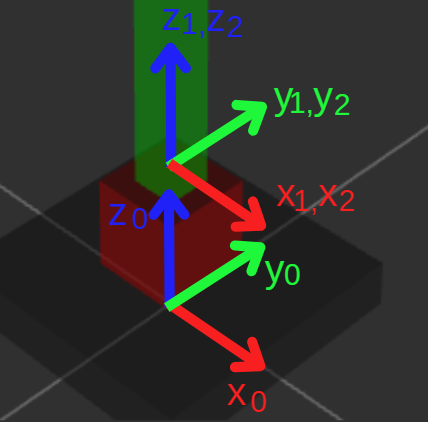

Figura 3: *Sistma de referencia {0} asociacdo al sistema inercial del robot *

En la Figura 3 se presenta los sistemas de referenia {1} y {2} cuyo origen comparten el mismo punto, el sistema {1} está asociado con el movimiento de la cintura del robot cuya junta rotacional gira con respecto al eje ${\widehat{\mathbf{z}} }_1$ y el sistema de referecia {2} está asociado con el sistema del hombro del robot el cual gira con respecto al eje ${\widehat{y} }_2$. La matriz de tranformación homógenea que describe la relaciones de posición y de orientación entre el sistema {1} y el sistema {0} es:

syms T_0_1 z_0_1 theta_0_1 T_1_2 theta_1_2 x_dot_0_1 x_ddot_0_1 

T_0_1

$$T\_0\_1 = T_{0,1}$$

T_0_1 = Tij(0,0,z_0_1,0,0,theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


x_dot_0_1

$$x\_dot\_0\_1 = {\dot{x}}_{0,1}$$


x_ddot_0_1

$$x\_ddot\_0\_1 = {\ddot{x}}_{0,1}$$

El sistema {2} está asociado a la artículación del hombro del robot y su movimiento es una rotación con respecto al eje ${\widehat{y} }_2$, la matriz de transformación de este sistema es:

T_1_2

$$T\_1\_2 = T_{1,2}$$

T_1_2 = Tij(0,0,0,0,theta_1_2,0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En la Figura 4 se presenta el sistema de referencia {3} asociado al codo del robot y el sistema de referencia {4} asociado al recodo de la muñeca del robot.

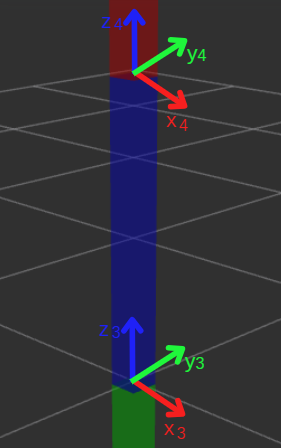

Figura 4: Sistema de referencia {3} asociado al codo del robot y sistema de referencia {4} asociado a la muñeca del robot

Las relaciones de posición y orientación entre el hombro y el codo del robot está dada en la matriz ${}^2{\mathbf{T}}_3$la cual describe la longitud del brazo del robot ${}^2z_3$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{y} }_3$.

syms T_2_3 z_2_3 theta_2_3 T_3_4 z_3_4 theta_3_4
T_2_3

$$T\_2\_3 = T_{2,3}$$

T_2_3 = Tij(0,0,z_2_3,0,theta_2_3,0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Las relaciones de posición y orientación entre el codo y el recodo del robot está dada en la matriz ${}^3{\mathbf{T}}_4$la cual describe la longitud del antebrazo del robot ${}^3z_4$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{y} }_4$.

T_3_4

$$T\_3\_4 = T_{3,4}$$

T_3_4 = Tij(0,0,z_3_4,0,theta_3_4,0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & z_{3,4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En la Figura 5 se presenta el sistema de referencia {4} asociado a la muñeca del robot y el punto del efector final asociado sobre el sistema {P}.

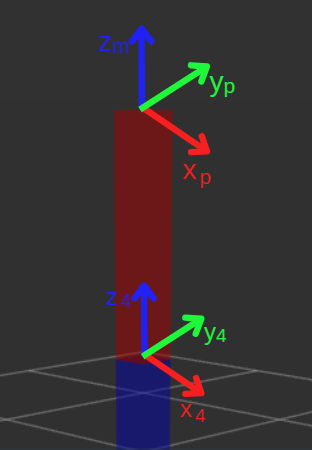

Figura 5: *Sistema de referencia {4} asociado a la muñeca del robot y el punto del efector final asociado sobre el sistema {P}.*

Las relaciones de posición y orientación entre el recodo y la muñeca del robot está dada en la matriz ${}^4{\mathbf{T}}_P$ la cual describe la longitud de la mano del robot ${}^4z_P$ y la restricción de la junta rotación asociada con el giro sobre el eje ${\widehat{z} }_P$.

syms T_4_P z_4_P theta_4_P

T_4_P

$$T\_4\_P = T_{4,P}$$

T_4_P = Tij(0,0,z_4_P,0,theta_4_P,0)

$$T\_4\_P = \left(\begin{array}{cccc} \cos\left(\theta_{4,P}\right) & 0 & \sin\left(\theta_{4,P}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{4,P}\right) & 0 & \cos\left(\theta_{4,P}\right) & z_{4,P}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelo cinemático directo de la postura

syms T_0_P

T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_P)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sigma_{2}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sigma_{2}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ -\sigma_{2} & 0 & \sigma_{3} & z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{4,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{2}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right)\\ \sigma_{3}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right) \end{array}$$

## Vector pose

xi_0_P = [T_0_P(1,4);T_0_P(2,4);T_0_P(3,4);T_0_P(1,1);T_0_P(2,2);T_0_P(3,3)]

$$xi\_0\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\sigma_{1}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{1}\\ z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right)\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z_{4,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right) \end{array}$$

## Modelo cinematico directo de las velocdades


$${}^0{\xi }_P=J_{\theta } \left(q\right)\dot{q}$$


syms J_theta q_dot theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 theta_dot_3_4 xi_dot_0_P
J_theta = jacobian(xi_0_P,[theta_0_1,theta_1_2,theta_2_3,theta_3_4])

$$J\_theta = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(\theta_{0,1}\right)\,\sigma_{2} & \cos\left(\theta_{0,1}\right)\,\sigma_{3} & \cos\left(\theta_{0,1}\right)\,\left(\sigma_{8}+z_{4,P}\,\sigma_{7}\right) & z_{4,P}\,\sigma_{7}\,\cos\left(\theta_{0,1}\right)\\ \cos\left(\theta_{0,1}\right)\,\sigma_{2} & \sin\left(\theta_{0,1}\right)\,\sigma_{3} & \sin\left(\theta_{0,1}\right)\,\left(\sigma_{8}+z_{4,P}\,\sigma_{7}\right) & z_{4,P}\,\sigma_{7}\,\sin\left(\theta_{0,1}\right)\\ 0 & -\sigma_{5}-\sigma_{6}-z_{2,3}\,\sin\left(\theta_{1,2}\right) & -\sigma_{5}-\sigma_{6} & -\sigma_{5}\\ -\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right)\,\sin\left(\theta_{0,1}\right) & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ -\sin\left(\theta_{0,1}\right) & 0 & 0 & 0\\ 0 & -\sigma_{4} & -\sigma_{4} & -\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{4}\,\cos\left(\theta_{0,1}\right)\\ \sigma_{2}=\sigma_{5}+\sigma_{6}+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sigma_{8}+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\sigma_{7}\\ \sigma_{4}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right)\\ \sigma_{5}=z_{4,P}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{6}=z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{7}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{8}=z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}$$

q_dot = [theta_dot_0_1; theta_dot_1_2; theta_dot_2_3;theta_dot_3_4]

$$q\_dot = \left(\begin{array}{c} {\dot{\theta }}_{0,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3}\\ {\dot{\theta }}_{3,4} \end{array}\right)$$

xi_dot_0_P = J_theta * q_dot% Ejemplo de valores para ángulos y longitudes

$$xi\_dot\_0\_P = \begin{array}{l} \left(\begin{array}{c} {\dot{\theta }}_{1,2}\,\cos\left(\theta_{0,1}\right)\,\sigma_{3}-{\dot{\theta }}_{0,1}\,\sin\left(\theta_{0,1}\right)\,\sigma_{2}+{\dot{\theta }}_{2,3}\,\cos\left(\theta_{0,1}\right)\,\left(\sigma_{7}+z_{4,P}\,\sigma_{6}\right)+{\dot{\theta }}_{3,4}\,z_{4,P}\,\sigma_{6}\,\cos\left(\theta_{0,1}\right)\\ {\dot{\theta }}_{1,2}\,\sin\left(\theta_{0,1}\right)\,\sigma_{3}+{\dot{\theta }}_{0,1}\,\cos\left(\theta_{0,1}\right)\,\sigma_{2}+{\dot{\theta }}_{2,3}\,\sin\left(\theta_{0,1}\right)\,\left(\sigma_{7}+z_{4,P}\,\sigma_{6}\right)+{\dot{\theta }}_{3,4}\,z_{4,P}\,\sigma_{6}\,\sin\left(\theta_{0,1}\right)\\ -{\dot{\theta }}_{1,2}\,\sigma_{2}-{\dot{\theta }}_{2,3}\,\left(z_{4,P}\,\sigma_{5}+\sigma_{4}\right)-{\dot{\theta }}_{3,4}\,z_{4,P}\,\sigma_{5}\\ -{\dot{\theta }}_{0,1}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right)\,\sin\left(\theta_{0,1}\right)-{\dot{\theta }}_{1,2}\,\sigma_{1}\,\cos\left(\theta_{0,1}\right)-{\dot{\theta }}_{2,3}\,\sigma_{1}\,\cos\left(\theta_{0,1}\right)-{\dot{\theta }}_{3,4}\,\sigma_{1}\,\cos\left(\theta_{0,1}\right)\\ -{\dot{\theta }}_{0,1}\,\sin\left(\theta_{0,1}\right)\\ -{\dot{\theta }}_{1,2}\,\sigma_{1}-{\dot{\theta }}_{2,3}\,\sigma_{1}-{\dot{\theta }}_{3,4}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}+\theta_{4,P}\right)\\ \sigma_{2}=z_{4,P}\,\sigma_{5}+\sigma_{4}+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sigma_{7}+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,P}\,\sigma_{6}\\ \sigma_{4}=z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)\\ \sigma_{5}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{6}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{7}=z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right) \end{array}$$